t=0:0.01:3-0.01;
v_ref=1;
analog=v_ref/2*sin(2*pi*t);
N=[2 3 4];
n1=round(analog./v_ref *2.^N(1)) * v_ref/2.^N(1);
n2=round(analog./v_ref *2.^N(2))* v_ref/2.^N(2);
n3=round(analog./v_ref *2.^N(3))* v_ref/2.^N(3);

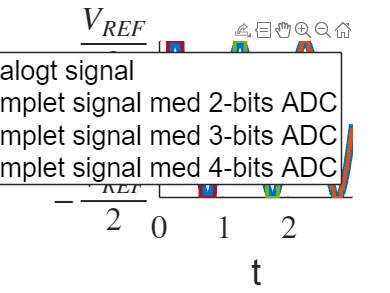

figure;

hold on;
plot(t,analog,'LineWidth',6,'Color',[0 0.4470 0.7410]);
plot(t(1:100),n1(1:100),'LineWidth',3,'Color',[0.6350 0.0780 0.1840]);
plot(t(101:200),n2(101:200),'LineWidth',3,'Color',[0.4660 0.6740 0.1880]);
plot(t(201:300),n3(201:300),'LineWidth',3,'Color',[0.8500 0.3250 0.0980]);
xlabel("t");
ylabel("[V]");
yticks([-0.5 0 0.5]);
yticklabels({"$-\frac{V_{REF}}{2}$","0","$\frac{V_{REF}}{2}$"});
set(get(gca,'ylabel'),'rotation',0);
set(gca, 'TickLabelInterpreter', 'latex');
set(gca, 'Fontsize', 25);
legend("Analogt signal","Samplet signal med "+N(1)+"-bits ADC","Samplet signal med "+N(2)+"-bits ADC","Samplet signal med "+N(3)+"-bits ADC",'FontSize',20);